# Lab 10 Sessió 1

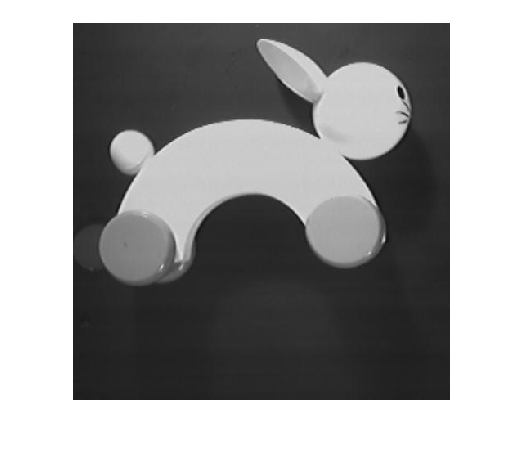

I = imread("rabbit.jpg");
imshow(I);

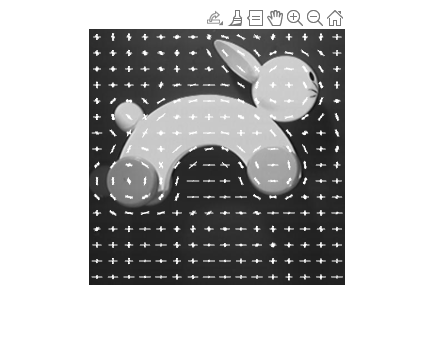


% Normalitzem l'imatge
I = imresize(I, [256 256]);

% Calculem Hog
[HoG, HoGdisplay] = extractHOGFeatures(I, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);

imshow(I);
hold on;
plot(HoGdisplay);
hold off;


[c, f] = getpts;

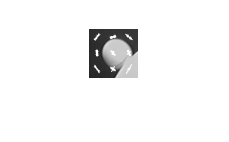

C = imcrop(I,[c-24, f-24, 48, 48]);

figure
imshow(C);
hold on
[HoGC, HoGdisplayC] = extractHOGFeatures(C, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);
plot(HoGdisplayC);
hold off;

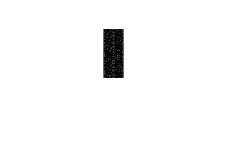


EF = reshape(HoG, [81, 14*14])'; % 81 features per 14 x 14 blocs (81 = 9 bins per 3x3 cells / block)
imshow(EF);


Semblanca = zeros([14*14, 1]);

for i = 1 : 14*14
    Semblanca(i) = sum(min(EF(i, :), HoGC));
end

[val, block_pos] = max(Semblanca)

val = 5.7578

block_pos = 19

## Exercici:

## Histogrames de color

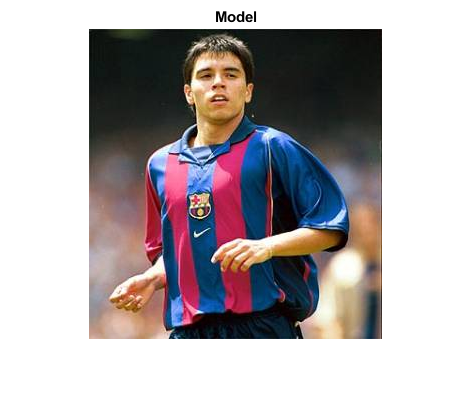

close all

% Llegim i mostrem l'imatge model
I = imread("team1.jpg");
figure, imshow(I), title('Model');

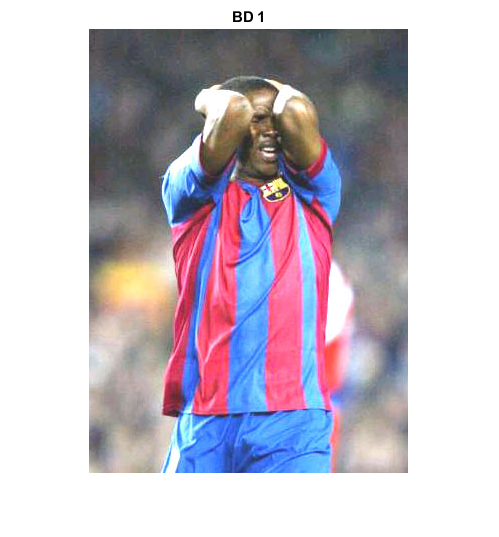

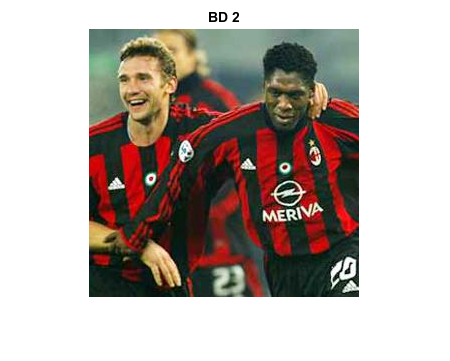

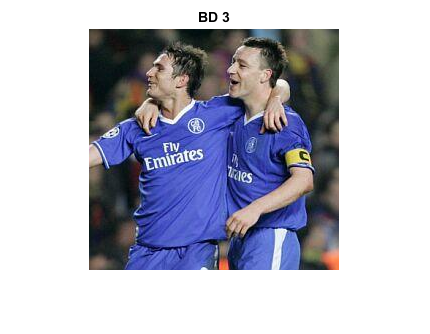

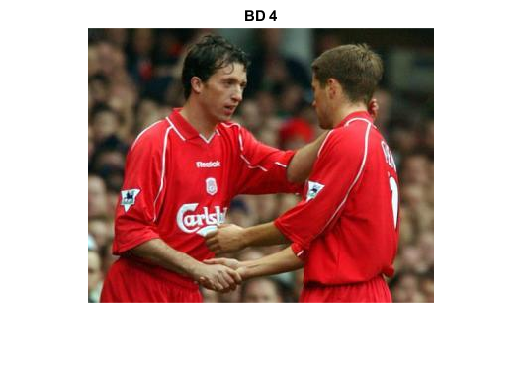

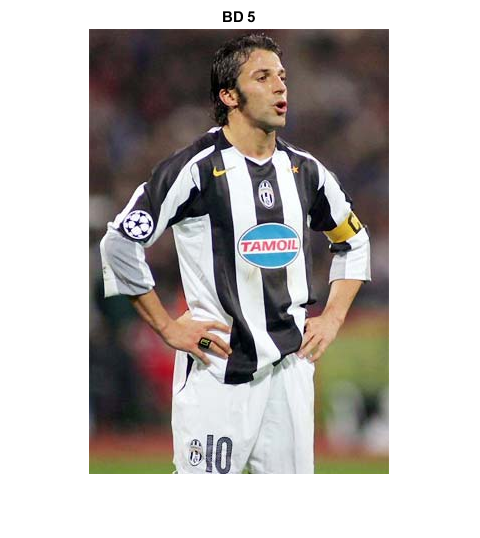


% Llegim les imatges a comparar
DB{1} = imread("team2.jpg");
DB{2} = imread("team5.jpg");
DB{3} = imread("team11.jpg");
DB{4} = imread("team12.jpg");
DB{5} = imread("team8.jpg");

% Les mostrem
for i = 1 : 5
    figure, imshow(DB{i}), title("BD "+i);
end

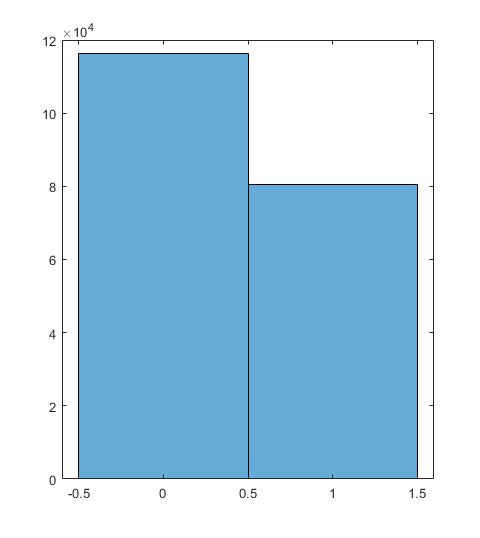

Error using plot
Not enough input arguments.

Error in untitled>CrearHistograma_rg (line 76)
    plot(h)


I = imresize(I, [256 256]);

for i = 1 : 5
    DB{i} = imresize(DB{i}, [256 256]);
end


% Calculem histogrames:
h = CrearHistograma_rg(I);


for i = 1 : 5
    h_db{i} = CrearHistograma_rg(DB{i})
end


function [h] = CrearHistograma_rg(I)

    sum_I = uint8(sum(I, 3));

    r = I(:, :, 1) ./ sum_I;
    g = I(:, :, 2) ./ sum_I;
    b = 1 - r - g;

    h = histogram([r g b]);
    plot(h)
end